# Predict Behaviour from Ca2+ signal using Machine learning

To see whether the information contained in the dendritic tree is able to predict the current behavioural state of the animal, we can try to use classification or regression between the Ca2+ signal and some behavioural metrics.

## Predictors

The approach requires some predictors, which, in our case are obtained from the GCaMP signal obtained from different part of the dendritic tree. We can use either the entire dendritic tree, or a subset of ROIs from the dendritic tree, or the average between different groups of ROIs (obtained, for example from a previous clustering analysis)

## Predictors preprocessing

Predictors correspond to Ca2+ signal. However, a number of preprocessing steps can be used:

- Signal normalization across ROIs. This is to minimize the effect of variations in signal amplitude due to instrumentation artefact. The best way to do it is to use the obj.rescaled_traces variables (which itself required to run the peak detection and rescaling on the arboreal_experiment_object). If you plan to study the modulation of the signal between ROIs in relation to the cell average signal, this step is mandatory.

- We can smooth the signal. This will reduce the impact of imaging noise. Use obj.filter_win

- We can use only a subset of timepoints. Typically, we may want to use only the signal amplitude when there is a bAP. This requires to run the peak detection on the arboreal_experiment_object.

- We may want to focus on the signal modulation around the cell average instead of the signal magnitude itself. 

## Observations

If we want to predict the behaviour from the Ca2+, we can use obj.behaviours. Classifiers require a binnarization step, while regression do not

## Example : SVM classifier on all behaviours

total dendritic length (-excluded branches) : 4254 um
The out-of-sample misclassification rate is 25.4%


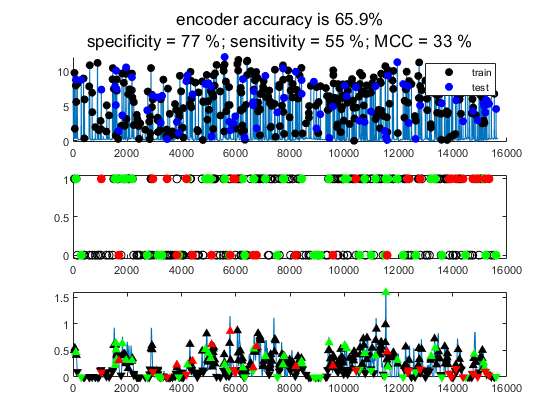

The out-of-sample misclassification rate is 41.7%


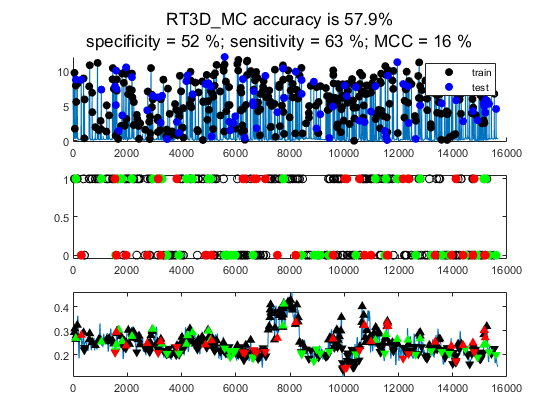

The out-of-sample misclassification rate is 43.9%


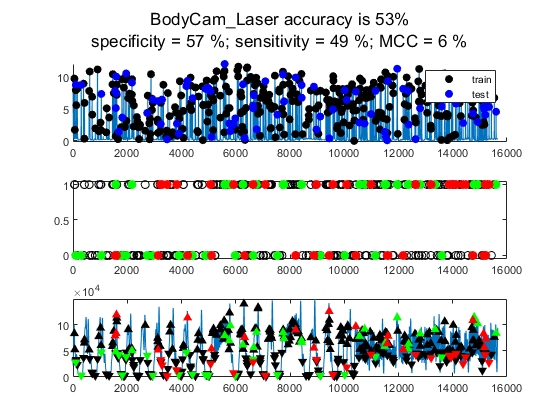

The out-of-sample misclassification rate is 31.9%


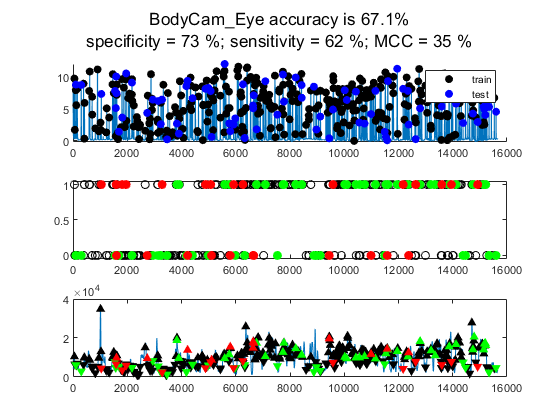

The out-of-sample misclassification rate is 15.4%


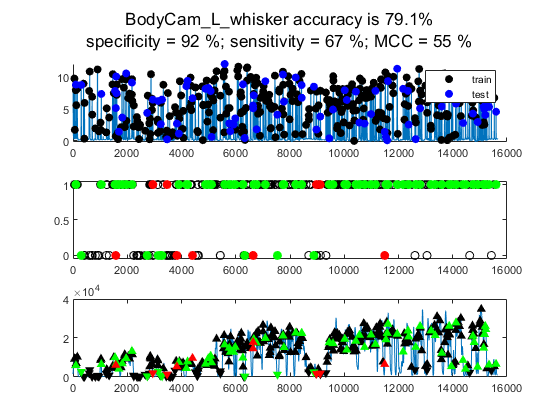

The out-of-sample misclassification rate is 32.8%


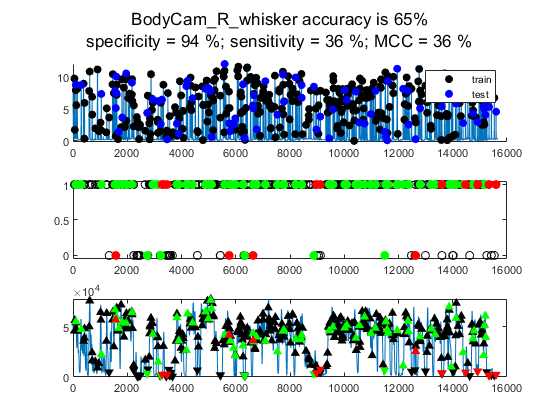

The out-of-sample misclassification rate is 47.3%


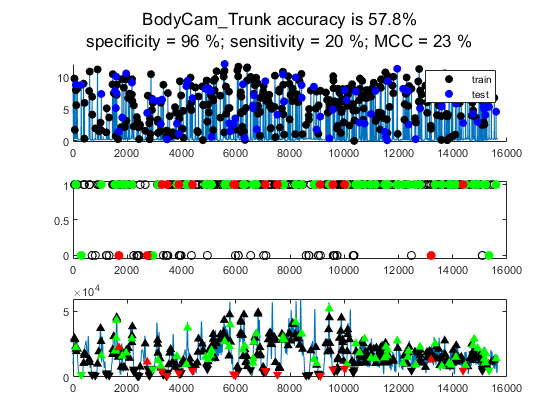

The out-of-sample misclassification rate is 21.9%


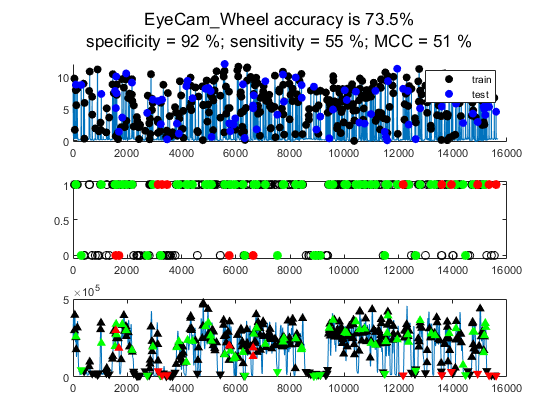

The out-of-sample misclassification rate is 33.2%


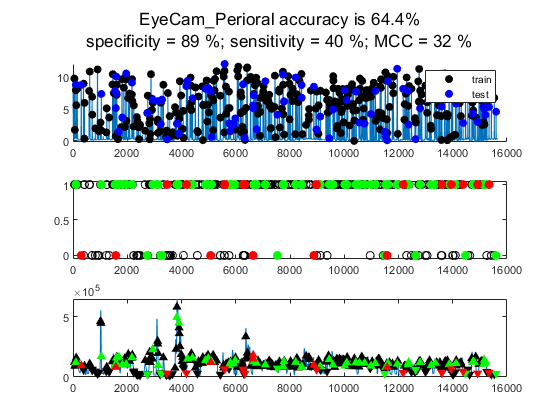

The out-of-sample misclassification rate is 34.7%


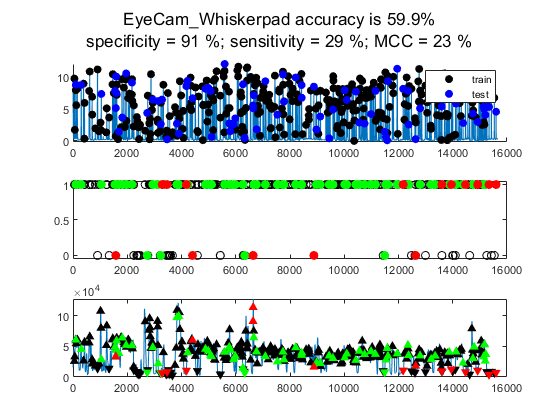

The out-of-sample misclassification rate is 22.4%


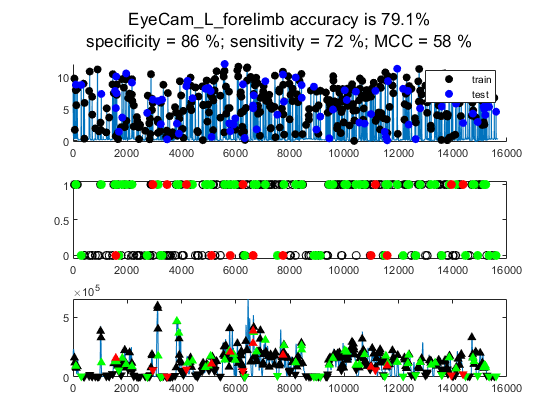

The out-of-sample misclassification rate is 23.1%


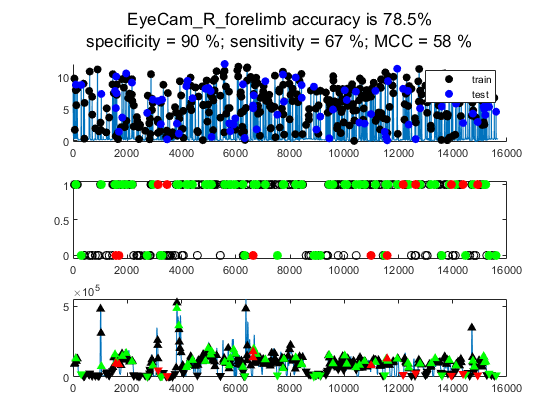

The out-of-sample misclassification rate is 30.7%


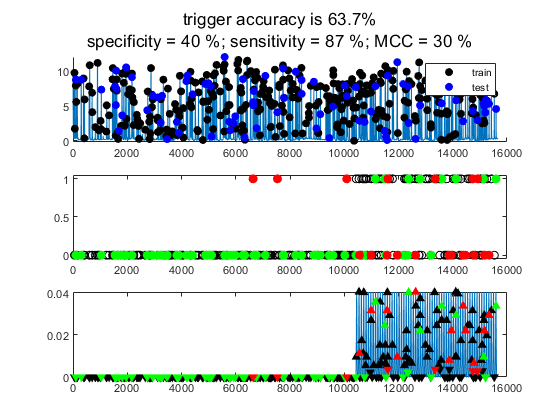

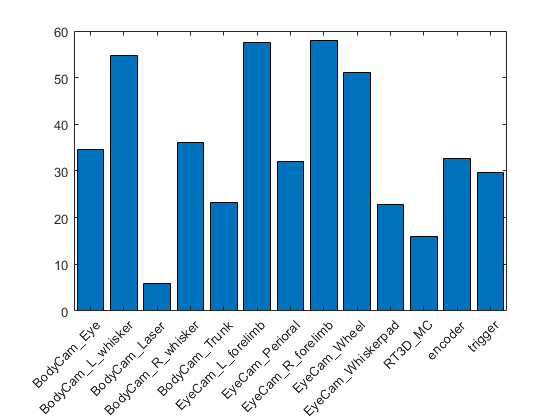

out = struct with fields:
        calcium: [15660×1 single]
        bin_beh: {[1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]}
        peak_tp: {[1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]}
    train_range: {[416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]  [416×1 logical]}
     prediction: {[83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]  [83×1 logical]}
       ful

% This is the default case : svm classifier
out = predict_behaviours(obj, true, 'svm')

Note that the predictor and the observations are sent to the base workspace in case you wanted to try different methods using the Classfication Learner App from MATLAB.

## Running a classifier on the rescaled peaks

The out-of-sample misclassification rate is 30.4%
The out-of-sample misclassification rate is 43.7%


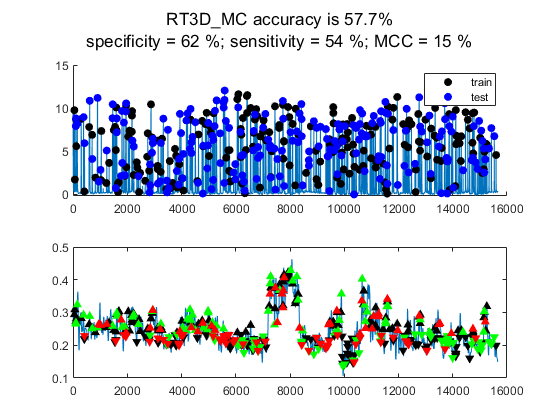

The out-of-sample misclassification rate is 49.1%


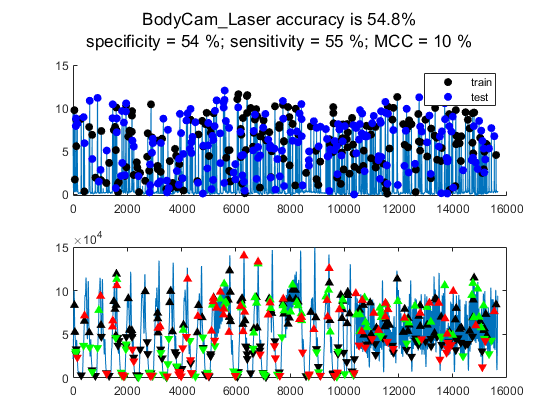

The out-of-sample misclassification rate is 37%


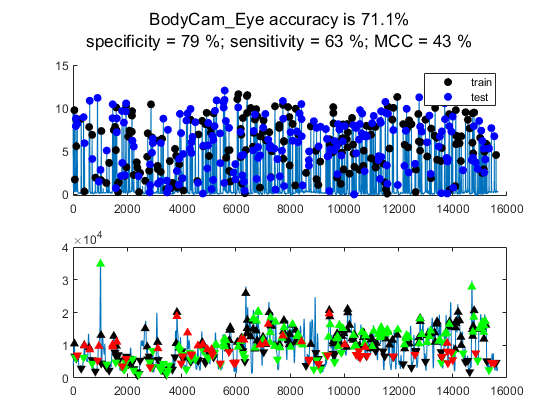

The out-of-sample misclassification rate is 12.8%


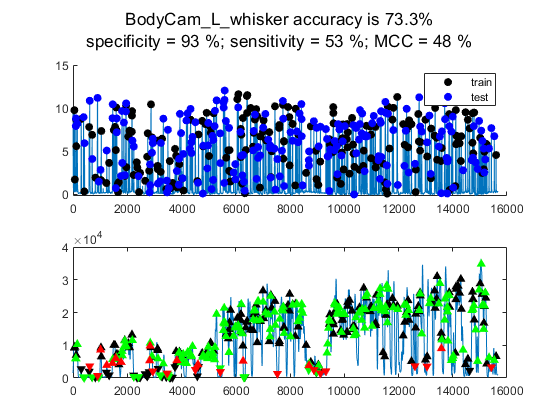

The out-of-sample misclassification rate is 36.1%


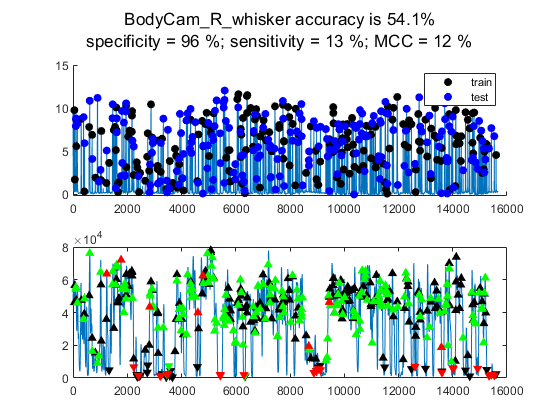

The out-of-sample misclassification rate is 47.8%


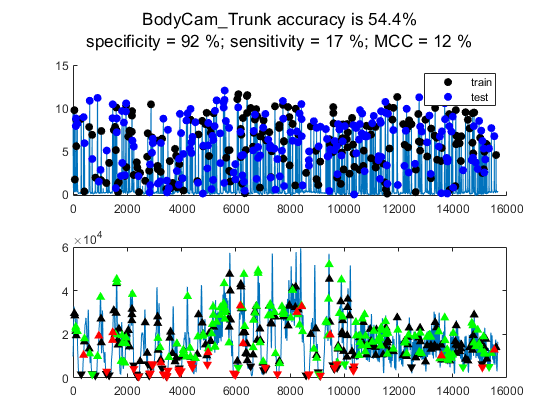

The out-of-sample misclassification rate is 18.5%


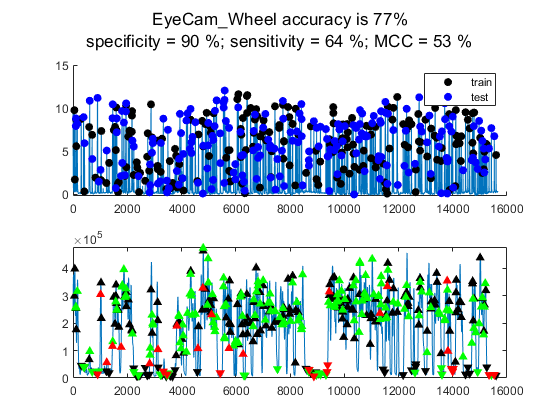

The out-of-sample misclassification rate is 32.5%


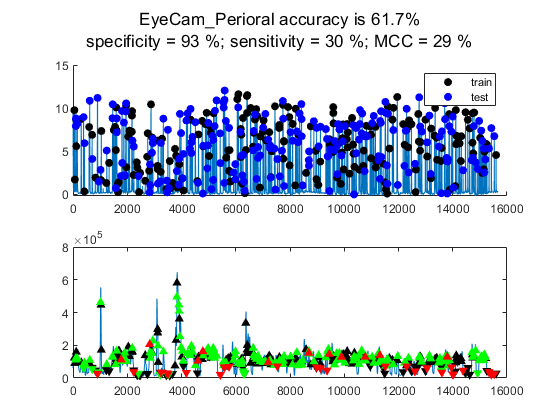

The out-of-sample misclassification rate is 40.8%


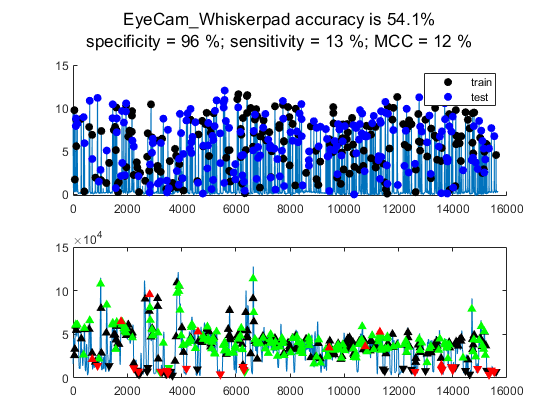

The out-of-sample misclassification rate is 25.6%


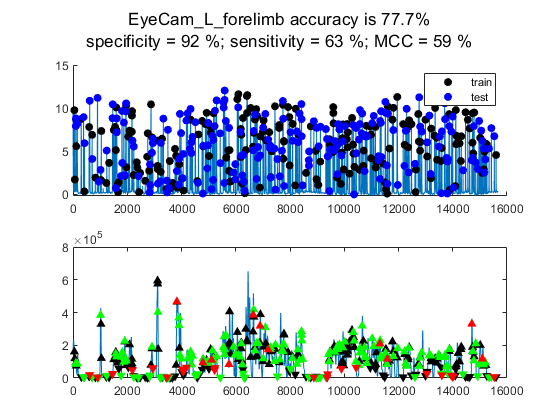

The out-of-sample misclassification rate is 24.6%


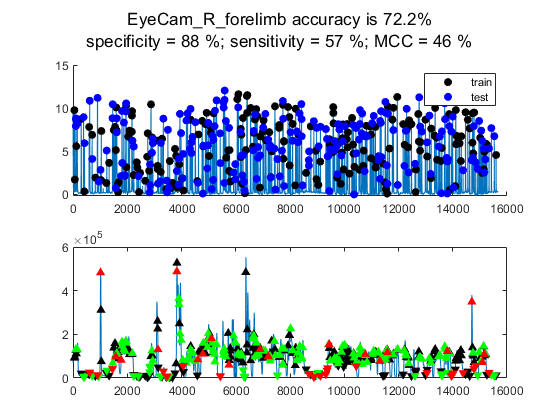

The out-of-sample misclassification rate is 39.8%


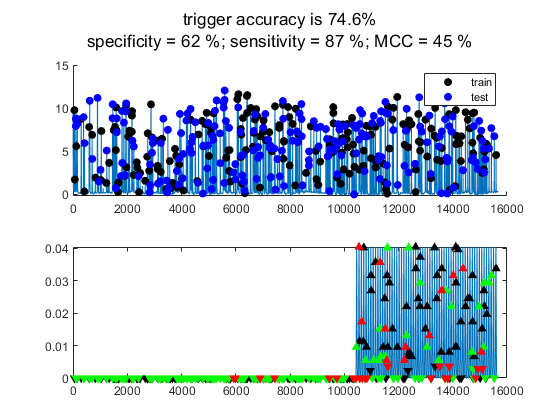

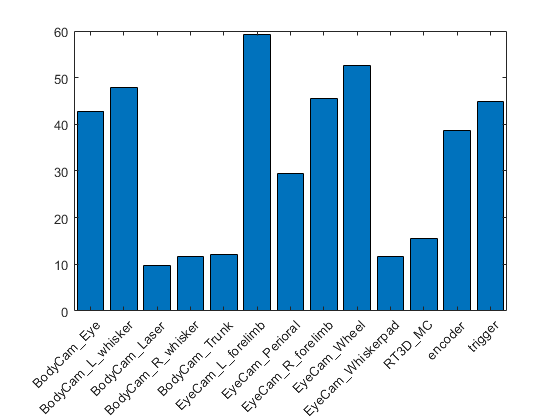

out = struct with fields:
        calcium: [15660×1 single]
        bin_beh: {[1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]  [1×416 logical]}
        peak_tp: {[1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]  [1×416 double]}
    train_range: {[1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]  [1×208 double]}
     prediction: {[208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]  [208×1 logical]}
       ful

% This will now take into account the magnitude of the response
out = predict_behaviours(obj, '', '', 'rescaled_peaks')

## Comparing two metrics for a given behaviour

The out-of-sample misclassification rate is 36.5%


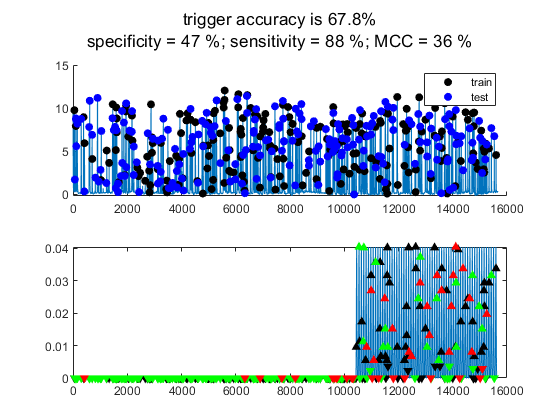

out1 = struct with fields:
        calcium: [15660×1 single]
        bin_beh: {[1×416 logical]}
        peak_tp: {[1×416 double]}
    train_range: {[1×208 double]}
     prediction: {[208×1 logical]}
       full_beh: {[1×15660 double]}
       beh_type: {'trigger'}
          score: {[67.8019 47.3684 88.2353 35.6037]}


% test using peak magnitude
out1 = predict_behaviours(obj, true, 'svm','rescaled_peaks',{'trigger'})

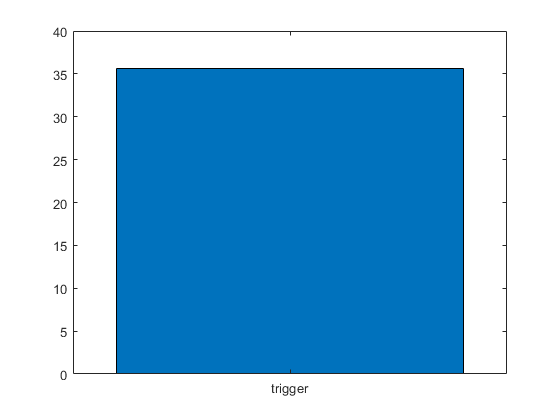

The out-of-sample misclassification rate is 37%


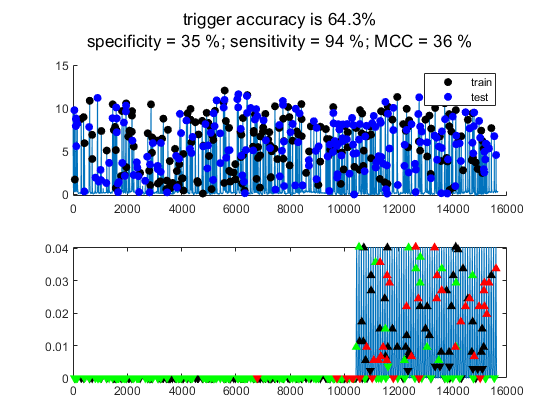

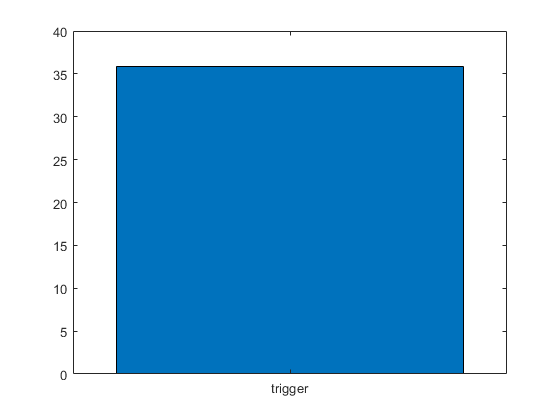

out2 = struct with fields:
        calcium: [15660×1 single]
        bin_beh: {[1×416 logical]}
        peak_tp: {[1×416 double]}
    train_range: {[1×208 double]}
     prediction: {[208×1 logical]}
       full_beh: {[1×15660 double]}
       beh_type: {'trigger'}
          score: {[64.3049 34.7826 93.8272 35.9028]}


% test using changes relative to the cell median
out2 = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'})

## Train classifier on phate groups

Doing PCA
PCA using random SVD
PCA took 0.024238 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 57
First iteration: k = 100
Number of samples below the threshold from 1st iter: 57
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.11997 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 22


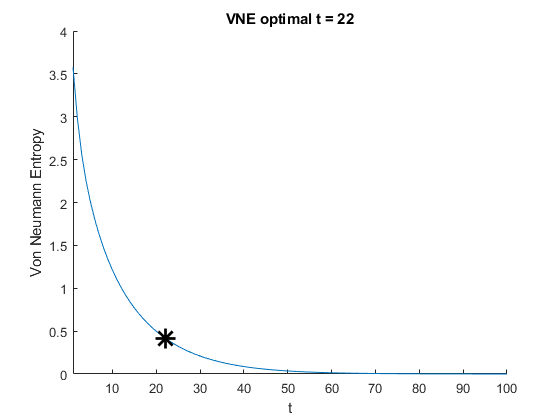

Diffusing operator
Diffusion took 0.0027848 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.013836 seconds
Doing classical MDS
CMDS took 0.0052381 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.590572         0.13264
           1        0.357757       0.0962853         1.97299               8
           2        0.277469        0.133809          1.5589               9
           3          0.1693        0.162375        0.980876               9
           4        0.070692        0.113337        0.558317               9
           5       0.0483617        0.103473        0.295701               8
           6       0.0356152       0.0942219        0.221762               8
           7         0.02778

tree_aspect = 'simple'

ans = 1

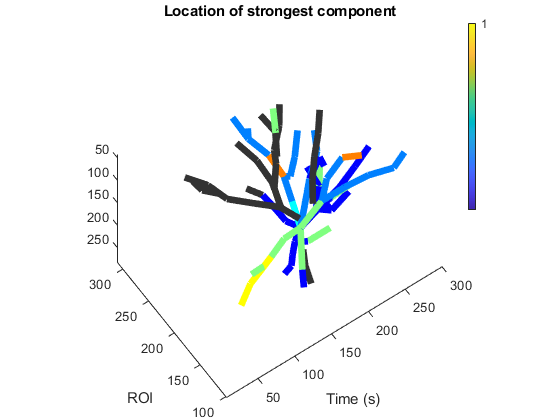

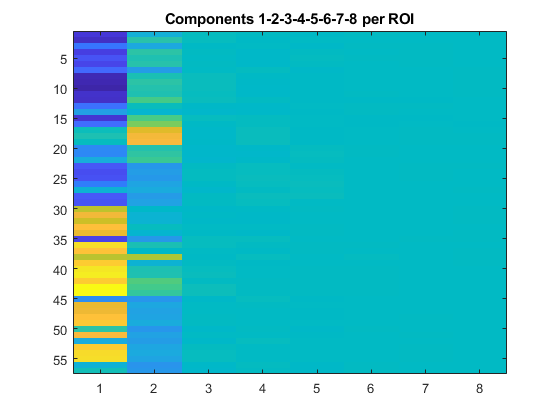

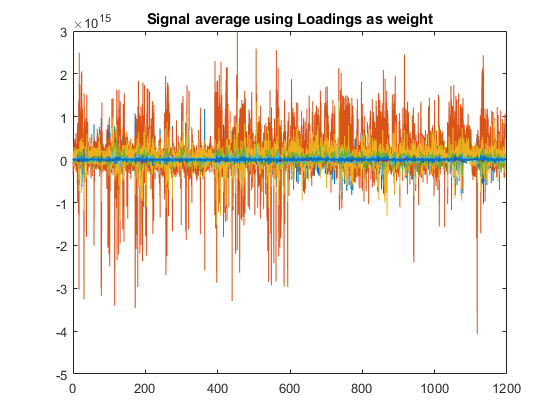

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

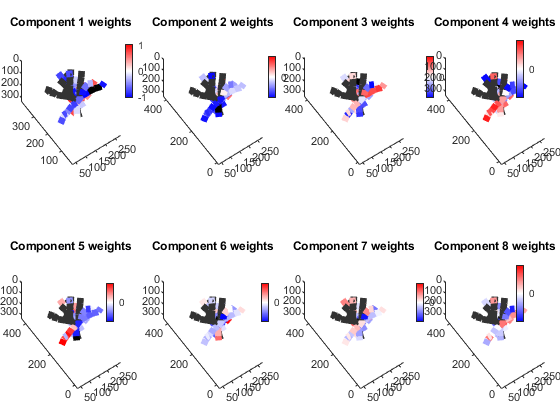

ans = 1×28 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


obj.get_dimensionality([], 'phate', 'peaks_subtracted', 8);

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

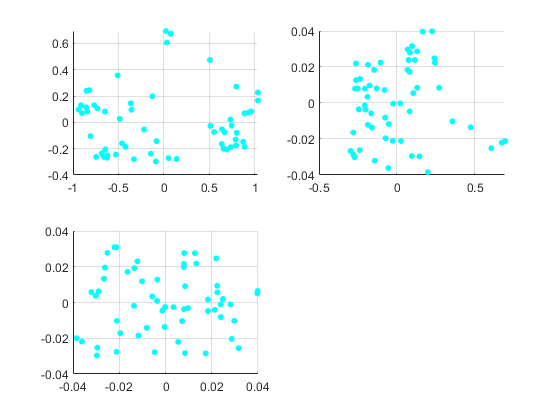

total dendritic length (-excluded branches) : 1140 um


tree_aspect = 'simple'

ans = 1

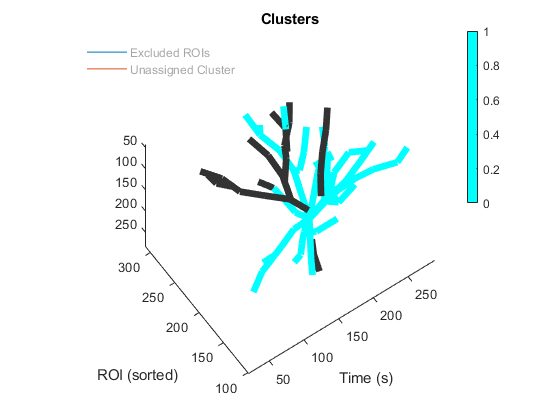

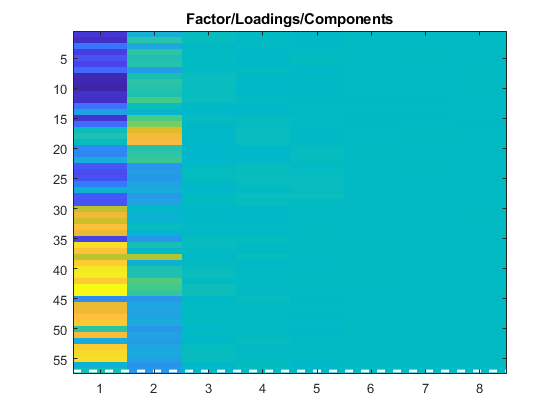

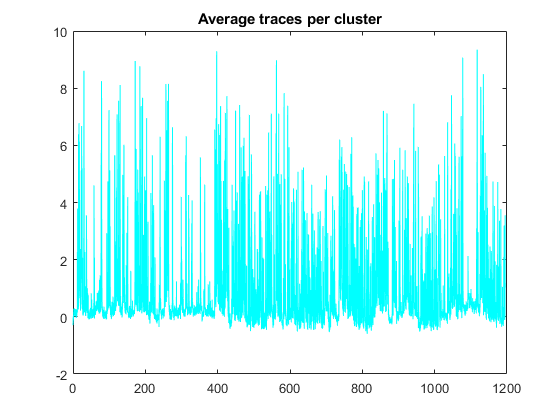

obj.cluster_factors('dbscan', []);

groups = {};
for el = 1:obj.dimensionality.N_clust
    groups{el} = find(obj.dimensionality.cluster_idx == el);
end


out1 = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'}, groups);

The out-of-sample misclassification rate is 46.6%


## Explore encoder classification using individual clusters, the average of clusters or all ROIs

The out-of-sample misclassification rate is 23.3%
The out-of-sample misclassification rate is 35.2%
The out-of-sample misclassification rate is 37.9%
The out-of-sample misclassification rate is 30.7%
The out-of-sample misclassification rate is 26.1%


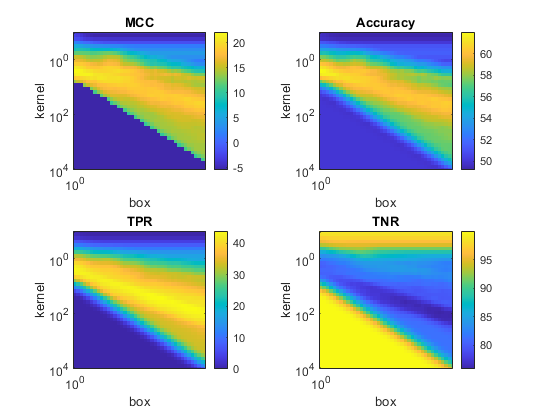

The out-of-sample misclassification rate is 36.4%


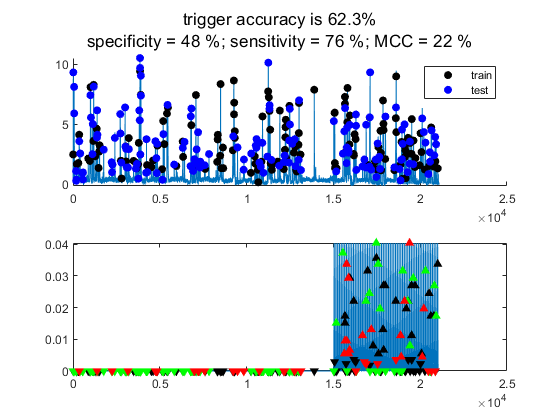

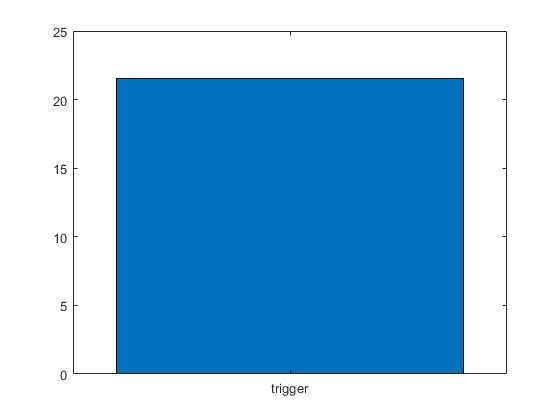

% We will use hyperparameter optimization
optimize = true;
gp_score = {};
for gp = 1:numel(groups)
    gp_score{gp} = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'encoder'}, groups{gp},optimize);
end

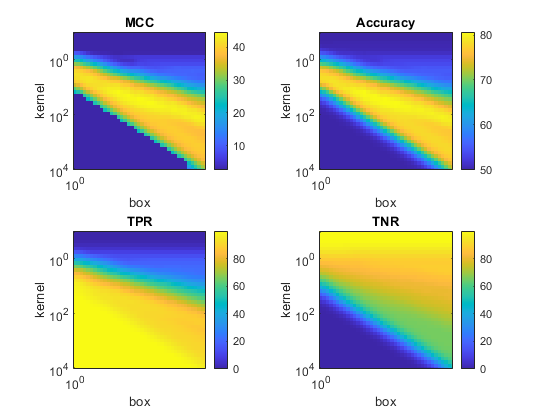

The out-of-sample misclassification rate is 18.6%


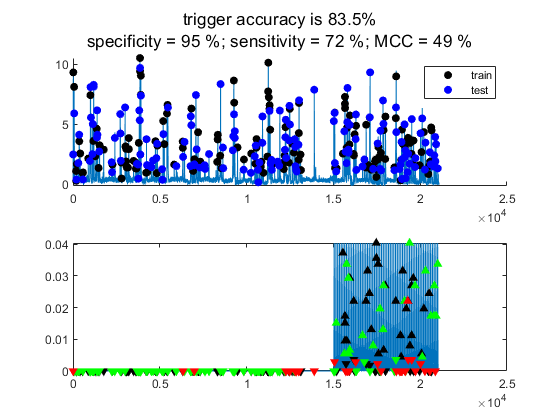


% Add score using the cluster averages as predictors
gp_score{end+1} = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'}, groups,optimize);

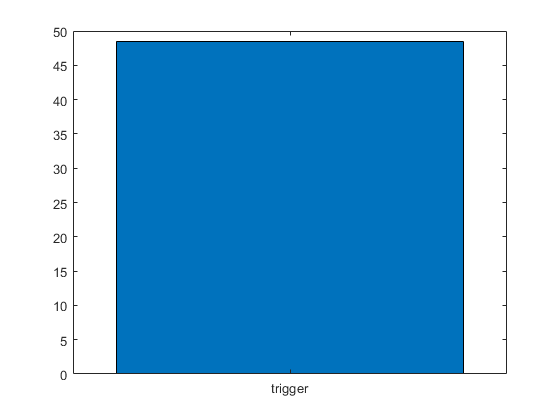

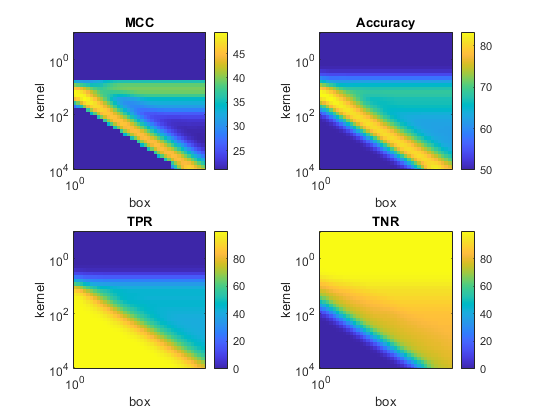

The out-of-sample misclassification rate is 18.6%


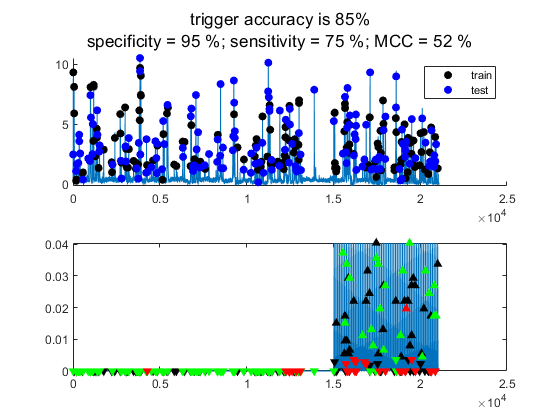

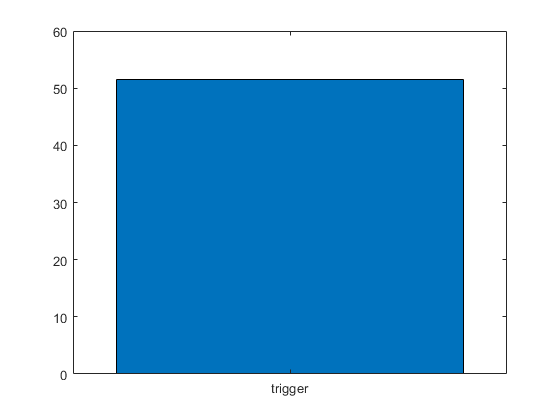


% Add score using all ROIs
gp_score{end+1} = predict_behaviours(obj, true, 'svm','subtracted_peaks',{'trigger'}, '',optimize);

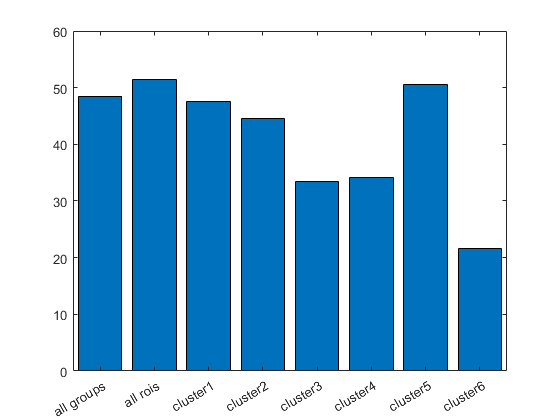

MCCs = cellfun(@(x) x.score{1}(4), gp_score);
figure(1001);clf();bar(categorical([strcat('cluster ', strsplit(num2str(1:numel(groups)),' ')),'all groups','all rois']), MCCs);